clf;
clear;

einstein = imread("../images/einstein_low_contrast.tif");
[M,N] = size(einstein)

M = 600

N = 490

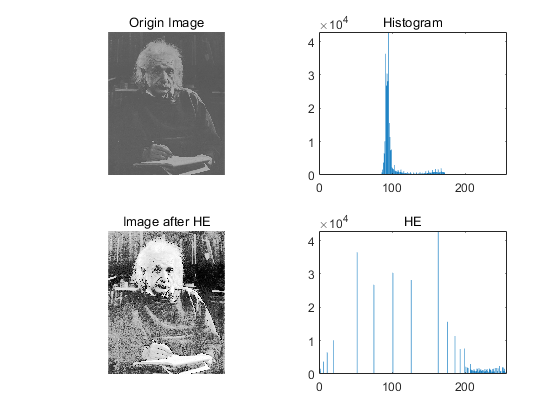

einstein = einstein(:,:,1);
%imshow(einstein);

I_hist = my_hist(einstein);

figure;
subplot(2,2,1);
imshow(einstein);title('Origin Image');
subplot(2,2,2);
bar(1:256,I_hist);title('Histogram');

% HE function
T = zeros(1,256);
for k = 1:256
    if k == 1
        T(k) = 255*I_hist(k)/M/N;
    else
        T(k) = T(k-1) + 255*I_hist(k)/M/N;
    end
end

% adapt HE
einstein_HE = zeros(M,N);
for m = 1:M
    for n = 1:N
        for k = 1:256
            if einstein(m,n) == k
                einstein_HE(m,n) = round(T(k));
            end
        end
    end
end

einstein_HE = uint8(einstein_HE);
% einstein_HE = histeq(einstein,256); % for check
subplot(2,2,3);
imshow(einstein_HE);title('Image after HE');    
subplot(2,2,4);
I_hist_HE = my_hist(einstein_HE);  
bar(1:256,I_hist_HE);title('HE');

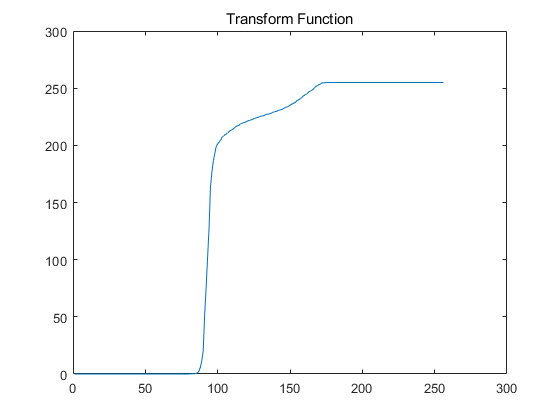


figure;
plot(T);title('Transform Function');

function output = my_hist(input)
[M,N] = size(input);
output = zeros(1,256);

for k = 1:256
    for m = 1:M
        for n = 1:N
            output(k) = output(k) + (input(m,n) == k);
        end
    end
end
end